# `LineSelectorChart`** Examples**

**Overview**

The `LineSelectorChart` manages multiple line plots, for which the *y*-data is on possibly different scales.The chart data comprises a numeric vector (`XData`) together with a numeric data matrix (`YData`). Each column of the `YData` is plotted against the `XData`, using a normalized scale so that all lines are visible together. Clicking on a line highlights it and shows its *y*-data on the true scale via *y*-axis limits and ticks. Clicking on another line changes the selection. Lines can be selected by clicking on the line itself, or programmatically by changing the `SelectedLineIndex` property of the chart.

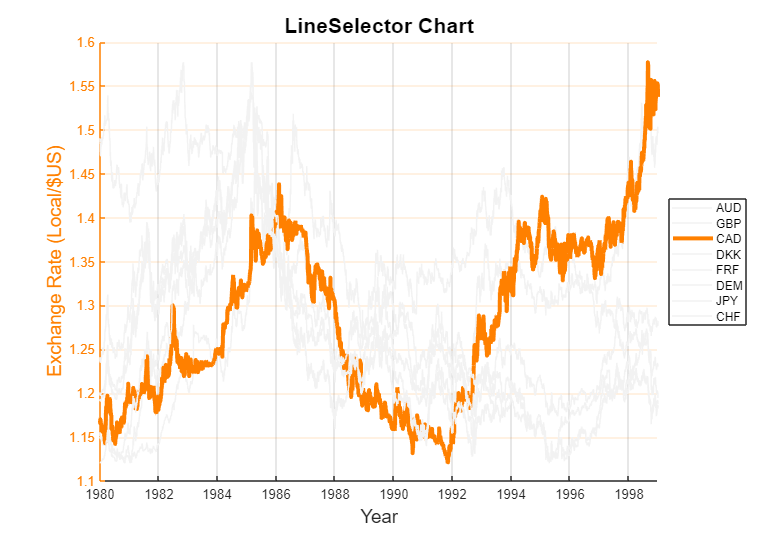

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "LineSelector.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "LineSelector.m"))) the source code for the `LineSelectorChart`.

See also:

- [`stackedplot`](matlab: doc("stackedplot")): An existing MATLAB chart for creating a stacked plot of several variables with a common x-axis.

## Load and prepare the exchange rate data.

The data comprises a timetable of exchange rates (local currency per $US) for eight currencies.

load( fullfile( chartsDocRoot(), "data", "Exchange.mat" ), "T" )

Create a numeric time vector, in fractional years, for use with the chart.

startDate = min( T.Date );
yearStart = dateshift( startDate, "start", "year" );
yearEnd = dateshift( startDate, "end", "year" );
fracYear = days( startDate - yearStart ) / days( yearEnd - yearStart );
t = startDate.Year + fracYear + years( T.Date - startDate );

Extract the currency codes.

codes = T.Properties.VariableNames;

## Create a figure for the chart.

f = exampleFigure( "Name", "LineSelectorChart Example" );

## Create the chart, specifying the data, figure and legend entries.

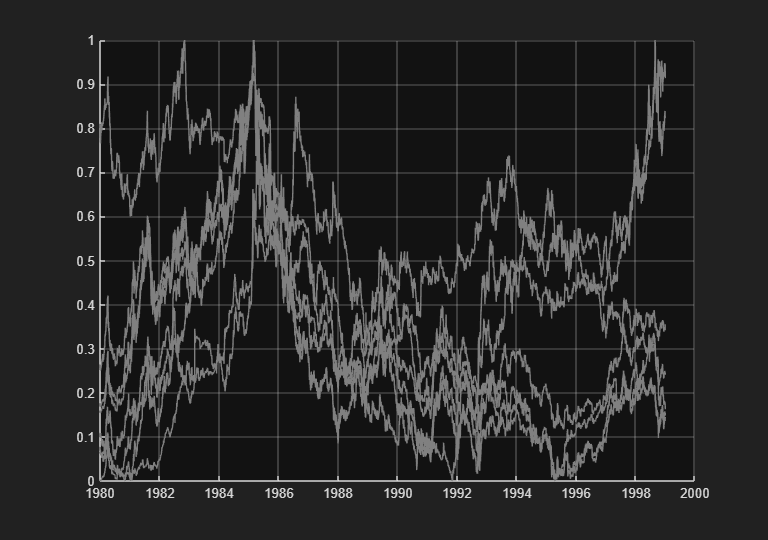

LSC = LineSelectorChart( "Parent", f, ...
    "XData", t, ...
    "YData", T.Variables );

## Annotate the chart and customize its appearance.

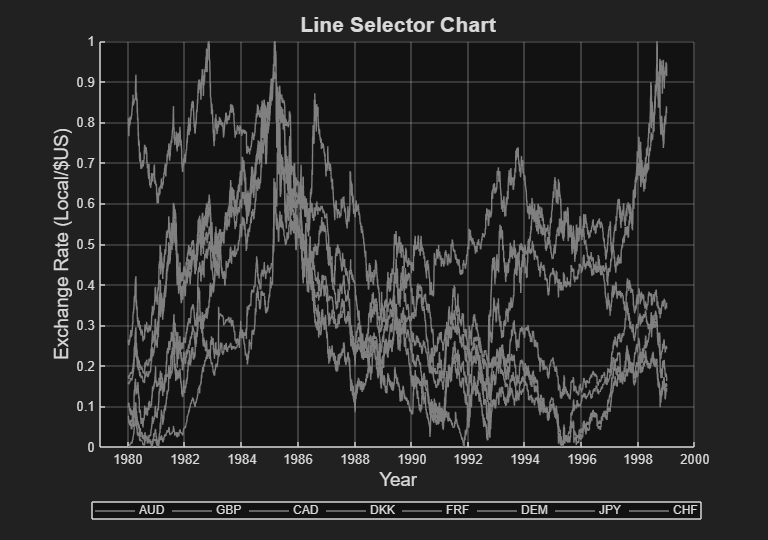

xlabel( LSC, "Year", "FontSize", 14 )
ylabel( LSC, "Exchange Rate (Local/$US)", "FontSize", 14 )
title( LSC, "Line Selector Chart", "FontSize", 16 )
xlim( LSC, [1979, 2000] )
legend( LSC, codes, "Location", "southoutside", ...
    "Orientation", "horizontal" )

## Change the chart data to show a particular decade.

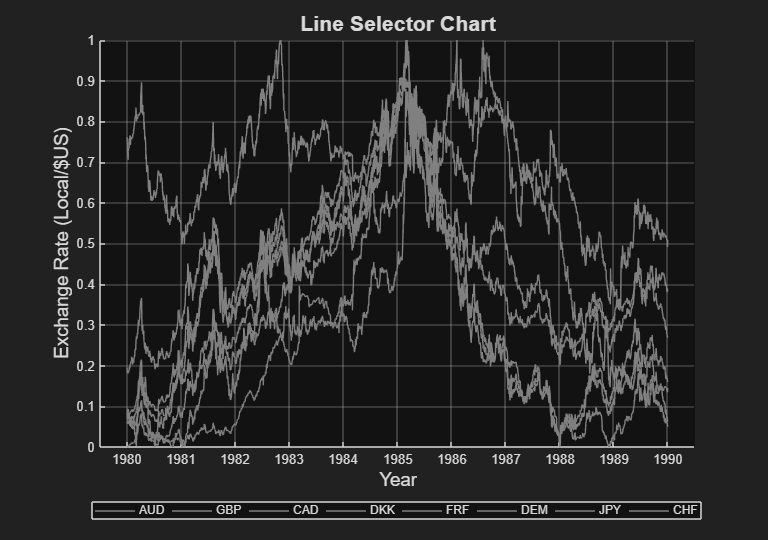

LSC.YData = LSC.YData(LSC.XData >= 1980 & LSC.XData < 1990, :);
xlim( LSC, [1979.5, 1990.5] )

## Show Australian and Canadian dollar exchange rates only.

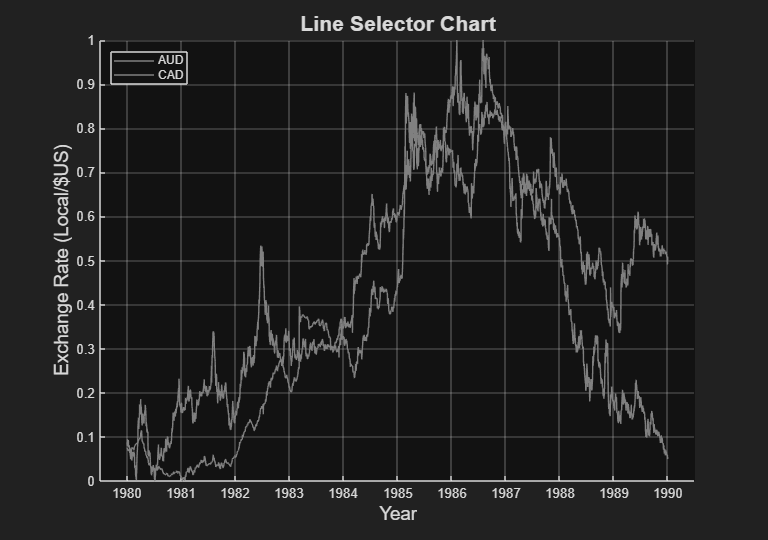

AUDCAD = ["AUD", "CAD"];
LSC.YData = LSC.YData(:, ismember( codes, AUDCAD ));
legend( LSC, AUDCAD, "Location", "northwest", ...
    "Orientation", "vertical" )

## Select a currency to highlight.

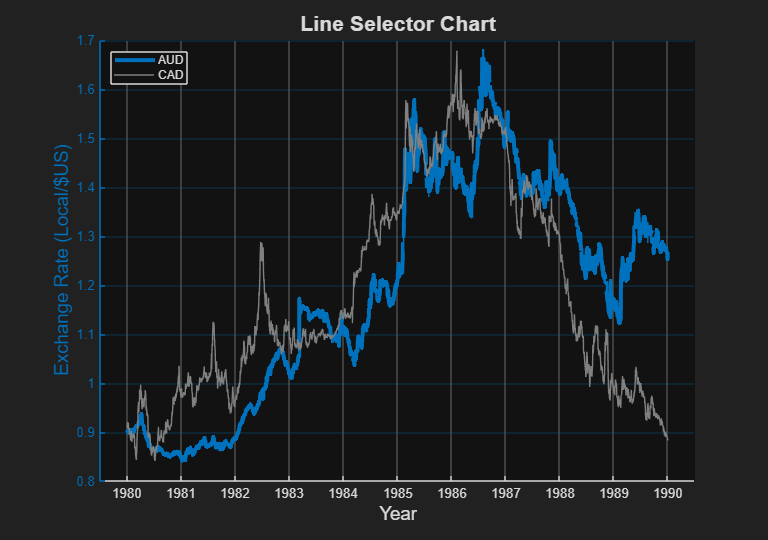

LSC.SelectedLineIndex = 1;

## Change the selection and highlight color.

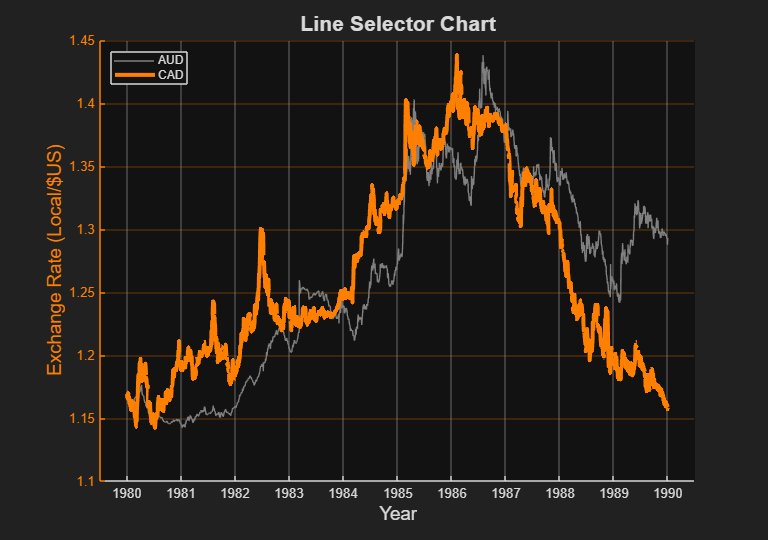

set( LSC, "SelectedLineIndex", 2, ...
    "SelectedColor", [1, 0.5, 0] )

## Include more lines in the chart, update the legend text and set the x-axis limits automatically.

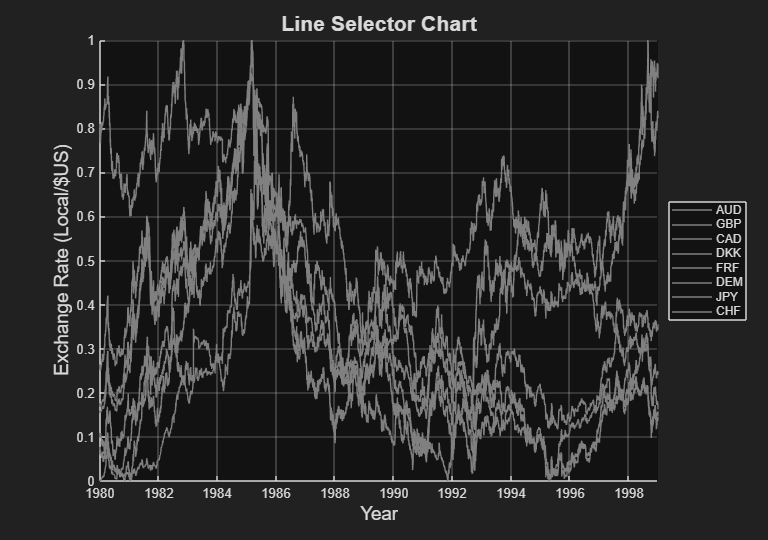

set( LSC, "XData", t, "YData", T.Variables )
drawnow()
legend( LSC, codes, "Location", "eastoutside" )
xlim( LSC, [-Inf, Inf] )

## Select a currency and change the color of the unselected lines.

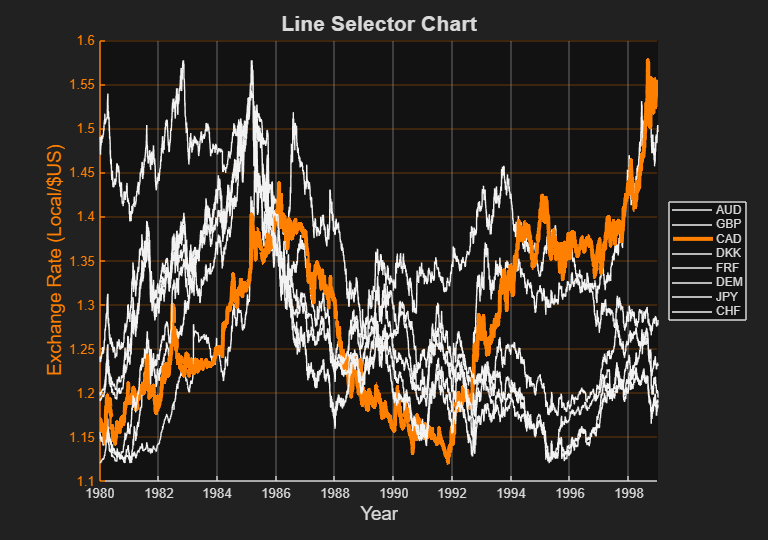

LSC.SelectedLineIndex = 3;
LSC.TraceColor = 0.95 * ones( 1, 3 );

## Deselect the line.

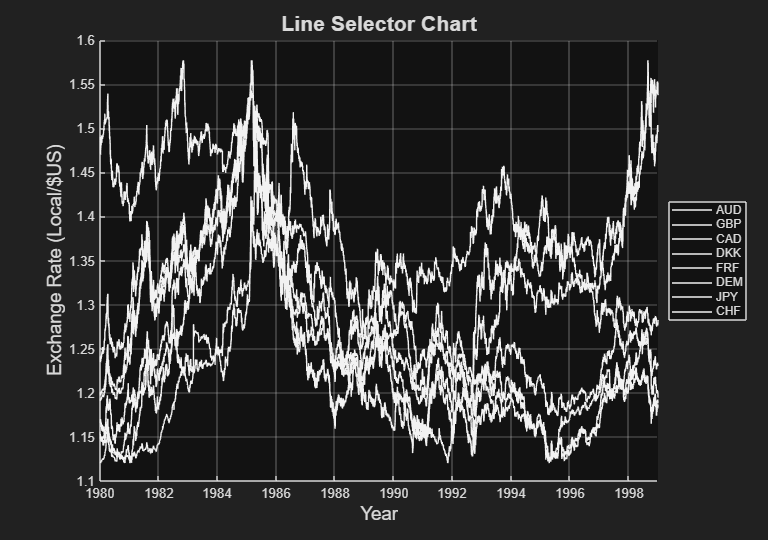

LSC.SelectedLineIndex = 0;

*Copyright 2018-2025 The MathWorks, Inc.*